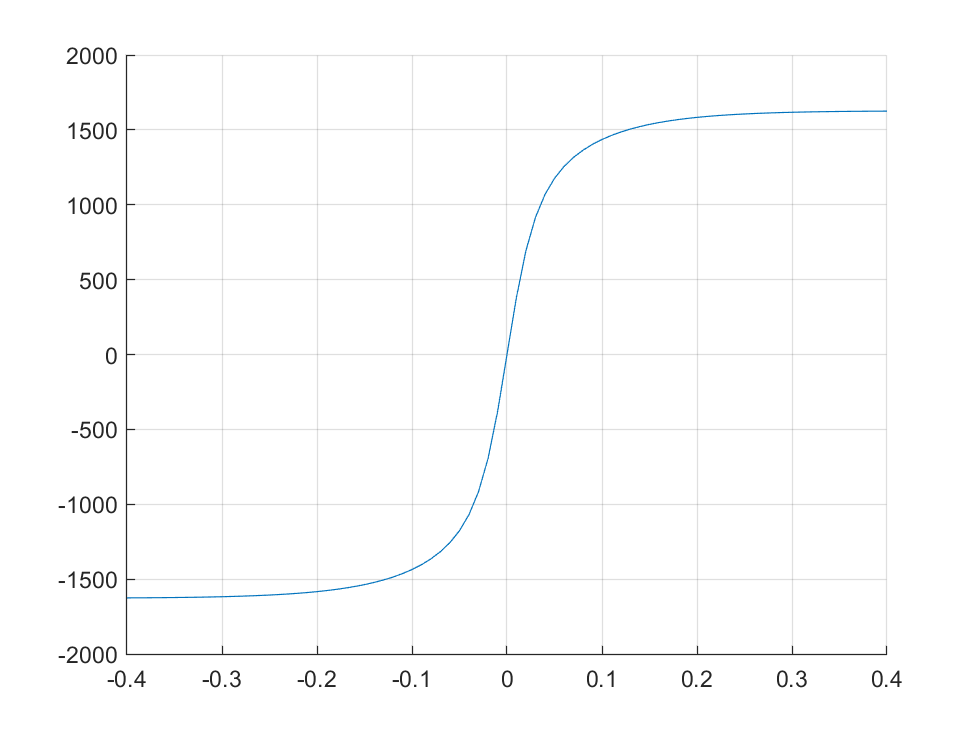

file = "C:\Users\Tom\OneDrive\Dokumente\racingteam\Hoosier_43075_16x7.5_10_LCO_RimWidth_7\mdl\Hoosier_43075_16x7.5_10_LCO_RimWidth_7_obfuscated.tir";

tyre = mftyre.v62.Model();
tyre.importTyrePropertiesFile(file)

p = tyre.Parameters;
p = struct(p);

SA = deg2rad(3);
SX = -0.4:0.01:0.4;
IA = deg2rad(0);
IP = 0.8E5;
FZ = 1200;
tyreSide = p.TYRESIDE;
[FX, FY] = mftyre.v62.eval(p, SA, SX, IA, IP, FZ, tyreSide);

figure
hold on
grid on
plot(SX, FX)

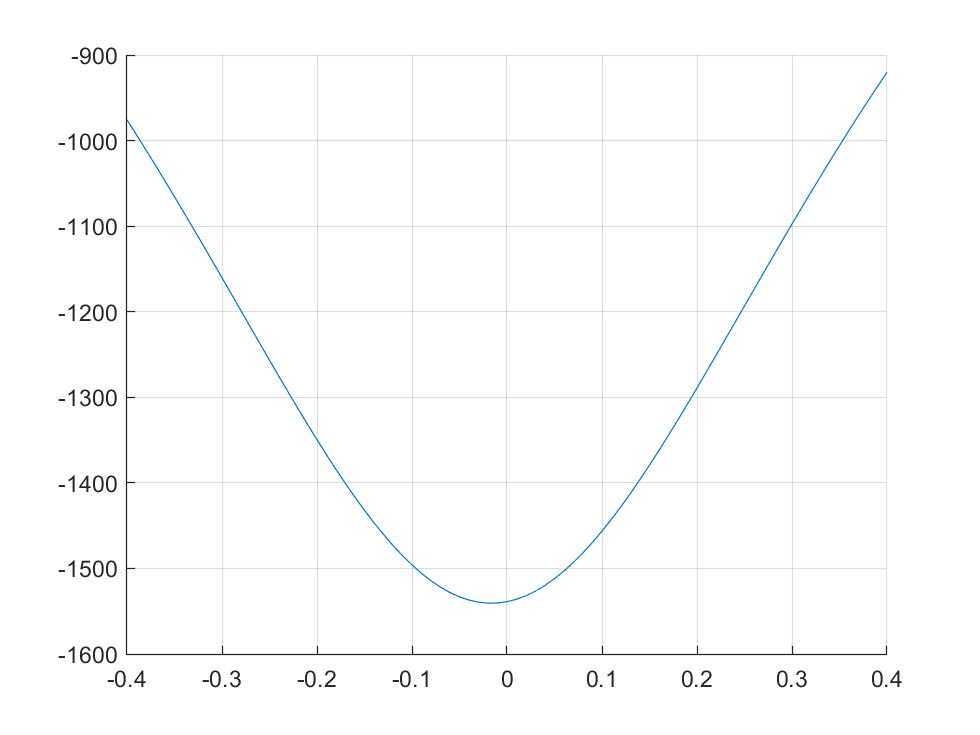


figure
hold on
grid on
plot(SX, FY)